# PhysioNet Challenge

2023-10-01

p = get_patients();
patient = p(1);
folderPath = "training/"+patient;
if ~exist(folderPath, 'dir')
    mkdir(folderPath);
end
url = "https://physionet.org/files/i-care/2.0/training/";
% readtable(url+patient+"/RECORDS")
data = webread(url+patient+"/RECORDS");
data = strsplit(data, '\n'); 
data = string(data);
patient_card = webread(url+patient+"/"+patient+".txt")

patient_card =     'Patient: 0284
     Hospital: A
     Age: 53
     Sex: Male
     ROSC: nan
     OHCA: True
     Shockable Rhythm: True
     TTM: 33
     Outcome: Good
     CPC: 1
     '


% filename = "0284_001_004_ECG.mat";
filename = data(1);
 
% disp(filename)
websave("training/"+patient+"/"+filename+".hea",url+patient+"/"+filename+".hea");
disp(filename+".hea saved")

0284_001_004_ECG.hea saved


websave("training/"+patient+"/"+filename+".mat",url+patient+"/"+filename+".mat");
disp(filename+".mat saved")

0284_001_004_ECG.mat saved


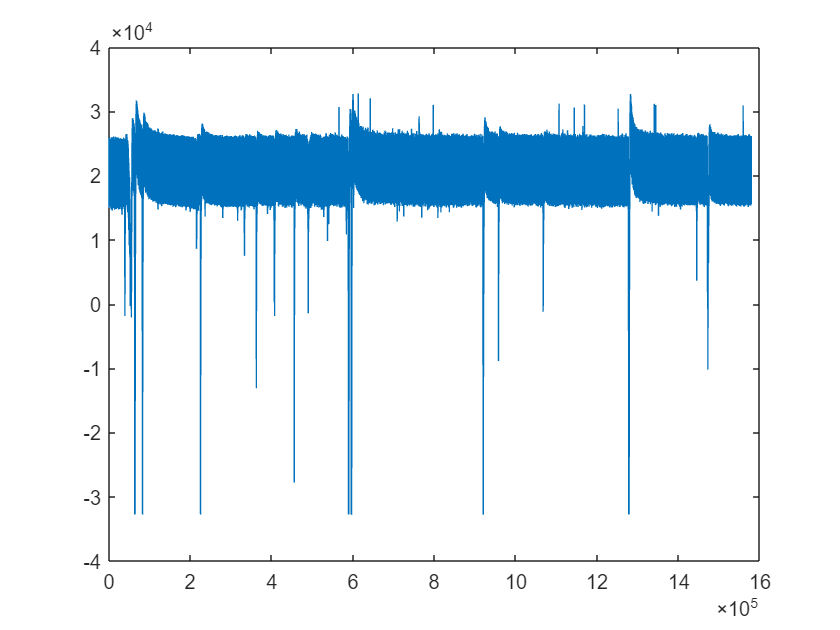

load("training/"+patient+"/"+filename+".mat")
plot(val)

function p = get_patients()
% Specify the URL
records_url = 'https://physionet.org/files/i-care/2.0/training/RECORDS';

% r = readtable(records_url)

% Read the content from the web
data = webread(records_url);

% Split the content by newline to get a cell array of strings
paths = strsplit(data, '\n');

% Remove empty cells, if any, from the cell array
paths = paths(~cellfun('isempty', paths));

% Initialize a cell array to hold the modified paths
patients = cell(size(paths));

% Loop over each path and perform the replacement operation
for i = 1:length(paths)
    patients{i} = regexprep(paths{i}, 'training', '');
    patients{i} = regexprep(patients{i}, '/', '');
end

% Display the original and modified paths
T = table(paths', patients', 'VariableNames', {'Path', 'Patient'});
% disp(T);
p = string(T.Patient);
end